clear;

# Read from File and Write to Audio Device

Read an MP3 audio file and play it through your default audio output device.

Create a `dsp.AudioFileReader` System object™ with default settings. Use the `audioinfo` function to return a structure containing information about the audio file.

%fileReader = dsp.AudioFileReader('speech_dft.mp3');
fn = 'D:\backup\doc\doc2018\放送大学\论文\自作試験\t4-matlab\16bit44kmono-small-28.wav';
fileReader = dsp.AudioFileReader(fn);
fileInfo = audioinfo(fn);

Create an `audioDeviceWriter` System object and specify the sample rate. Call `setup` to reduce the computational load of initialization in an audio stream loop.

deviceWriter = audioDeviceWriter(...
    'SampleRate',fileInfo.SampleRate);
setup(deviceWriter,...
    zeros(fileReader.SamplesPerFrame,fileInfo.NumChannels));

Send to sepctumAnalyzer

spa = dsp.SpectrumAnalyzer;
spa.ViewType = 'Spectrum';
spa.SampleRate = fileInfo.SampleRate;
%spa.SpectralAverages = 1;
spa.SpectrumType = 'RMS';
spa.PlotAsTwoSidedSpectrum = false;
%spa.RBWSource = 'Auto';
%spa.PowerUnits = 'dBW';


In an audio stream loop, read an audio signal frame from the file, and write the frame to your device.

% while ~isDone(fileReader)
%    audioData = fileReader();
%    deviceWriter(audioData);
% end


Send to scope

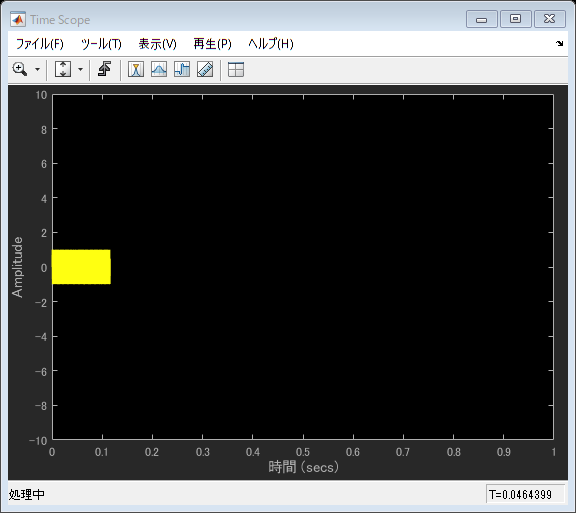

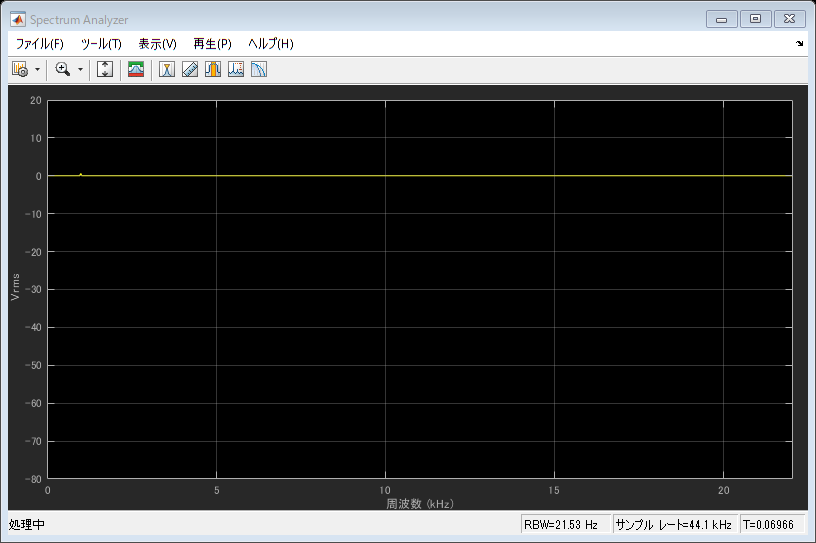

scope = dsp.TimeScope('SampleRate',fileInfo.SampleRate,'TimeSpan',fileInfo.Duration);
while ~isDone(fileReader)
    audioData = fileReader();
    %deviceWriter(audioData);
    scope(audioData);
    spa(audioData);
end

Close the input file and release the device.

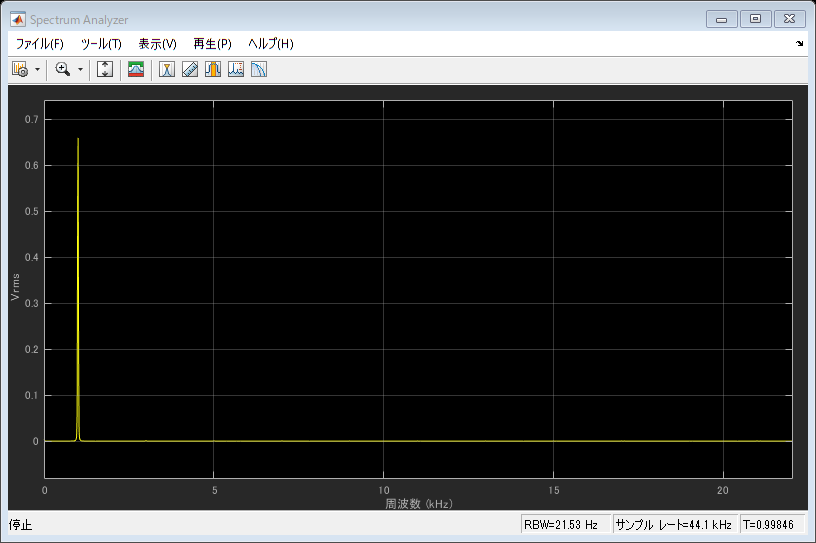

release(spa);

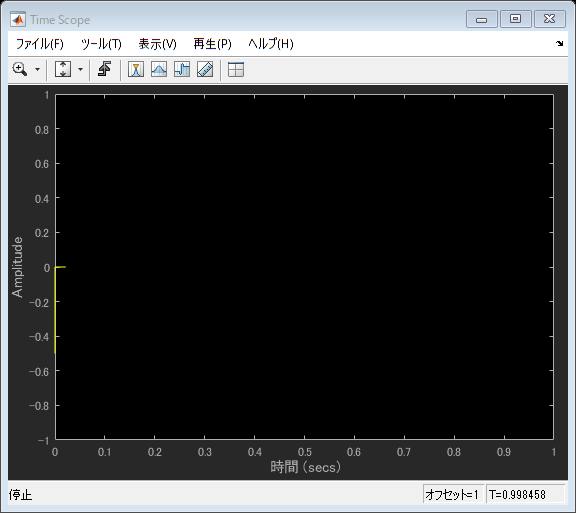

release(scope);

release(fileReader);
release(deviceWriter);

# MEMO

- This script base on ReadFromFileAndWriteToAudioDeviceExample